rosshutdown

Shutting down global node /matlab_global_node_37265 with NodeURI http://192.168.1.100:62241/


setenv('ROS_MASTER_URI','http://192.168.1.200:11311')
setenv('ROS_IP','192.168.1.100')
rosinit('http://192.168.1.200:11311','NodeHost','192.168.1.100');

Initializing global node /matlab_global_node_89820 with NodeURI http://192.168.1.100:62310/


clear
clc

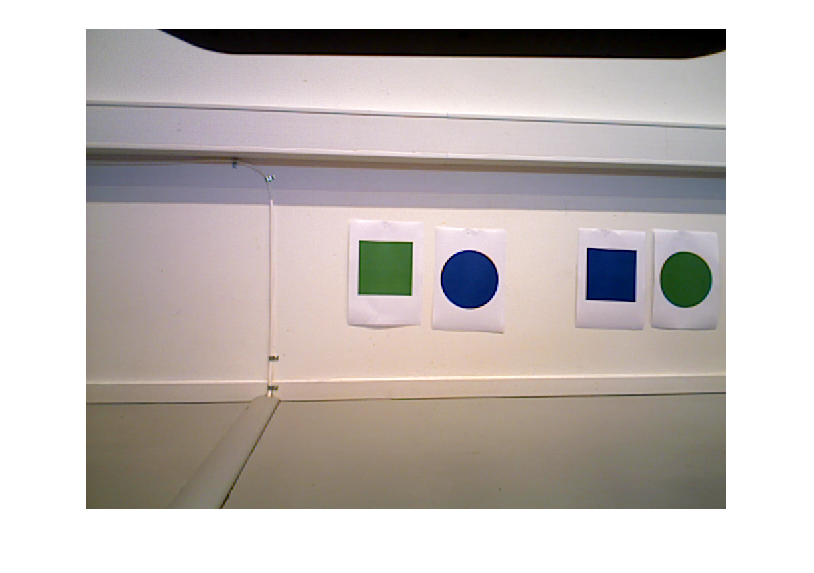

% Grap image from camera
if ismember('/camera/rgb/image_color/compressed',rostopic('list'))
    imsub = rossubscriber('/camera/rgb/image_color/compressed');
end

if ismember('/camera/rgb/image_raw',rostopic('list'))
    imsub = rossubscriber('/camera/rgb/image_raw');
end

imgraw = receive(imsub); % a serialised image
img = readImage(imgraw); % decode image
figure
imshow(img);

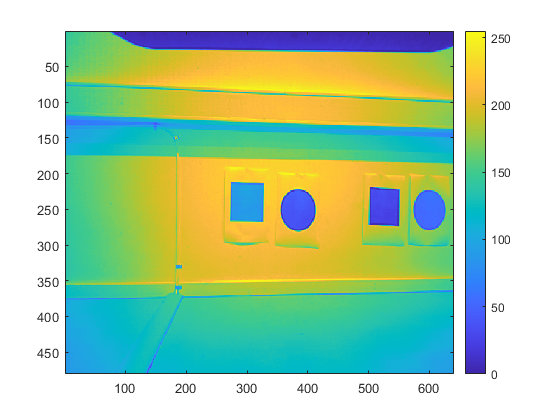

m1g = rgb2gray(img);
%imshow(m1)
imagesc(m1g), colorbar

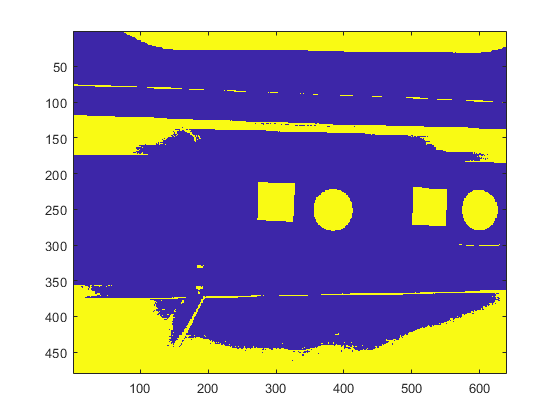

m1b = m1g < 130; % Image Segmenter APP
imagesc(m1b)

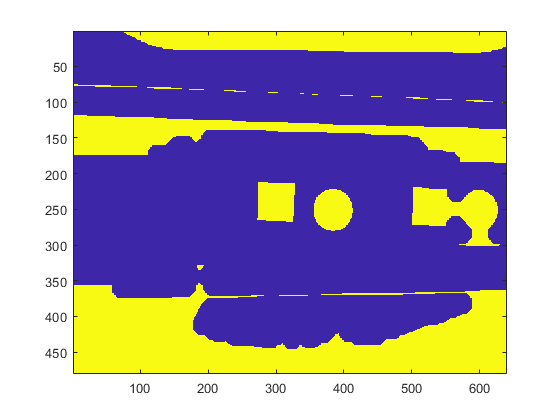

m1bd = imclose(m1b, strel('disk', 15)); % fill holes in disc
imagesc(m1bd)

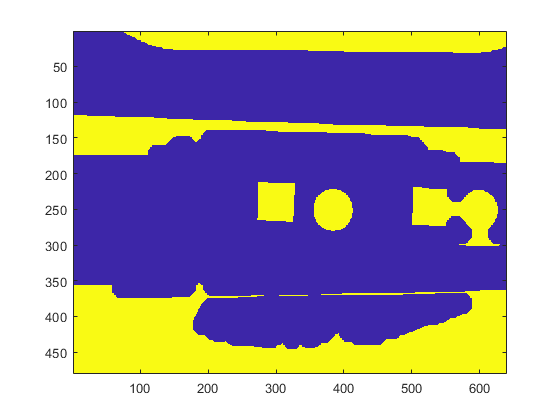

m1be = bwpropfilt(m1bd, 'Area', [1000 200000]); % remove small blobs..
imagesc(m1be)

## visualize / analyze..

m1lab = bwlabel(m1be);
m1prop = regionprops(m1lab, 'Area', 'Eccentricity') % find features..

m1prop = 6×1 struct array with fields:
    Area
    Eccentricity


## remove high Eccentricity..

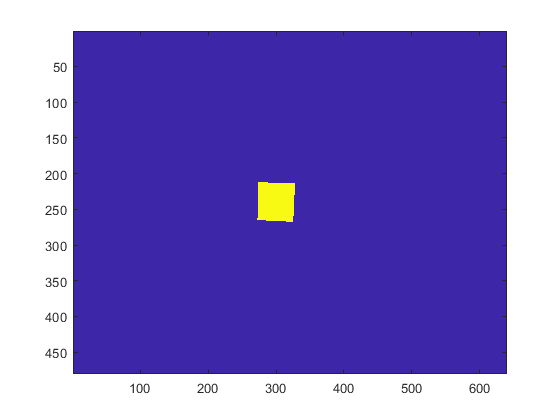

m1bf = bwpropfilt(m1be, 'Eccentricity', 1, 'smallest');
imagesc(m1bf)

## Make a decision..

m1prop = regionprops(m1bf, 'Area', 'Eccentricity'); % find features..
if m1prop.Eccentricity < 0.6, 
    disp('GOAL!'), 
end

GOAL!
